# Saleh-Valenzuela信道模型

室内信道时延分布中存在多簇现象，每一簇有多条射线，每一簇及每一簇内射线服从泊松过程。每一路径的时延不是采样周期的整数倍而是任意大小。可以证明簇间到达时间分布和簇内射线间到达时间分布均为指数分布。

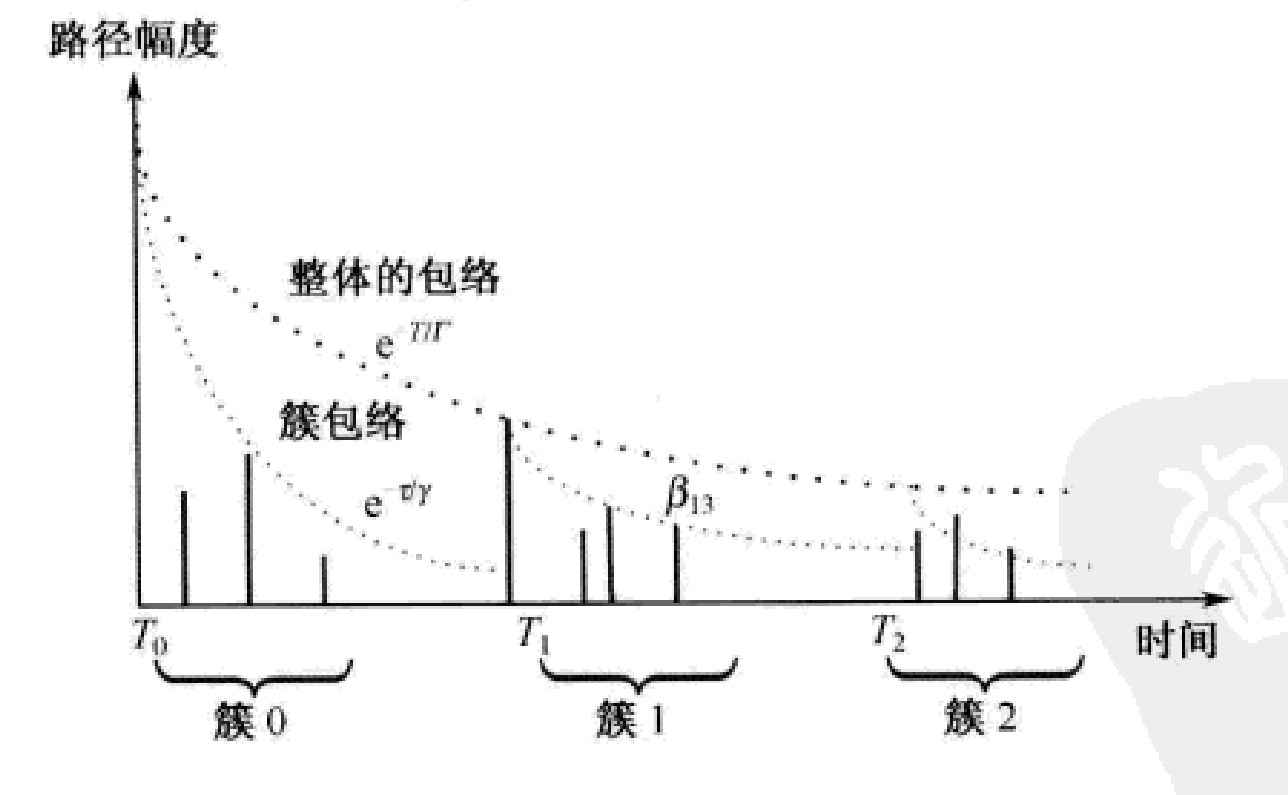

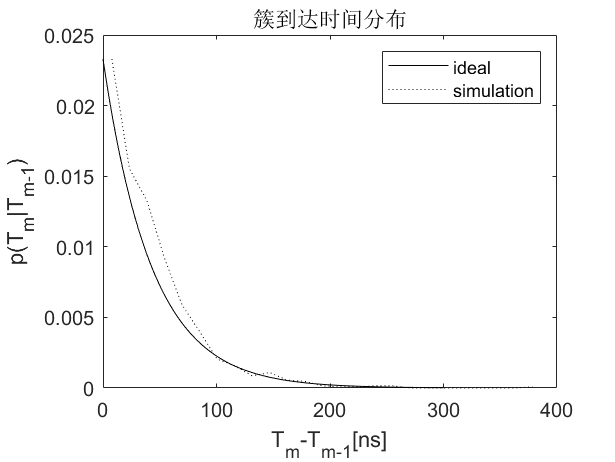

clear;
clc;
Lam = 0.0233;
lambda = 2.5;
Gam = 7.4;
gamma = 4.3;
N = 1000;%信道数
power_nom = 1;
std_shdw = 3;
t1  = 0:300;
t2 = 0:0.01:5;
p_cluster = Lam*exp(-Lam*t1);% 理想指数PDF
h_cluster = exprnd(1/Lam,1,N);
[n_cluster x_cluster] = hist(h_cluster,25);

figure()
plot(t1,p_cluster,'k')
hold on;
plot(x_cluster,n_cluster*p_cluster(1)/n_cluster(1),'k:')
legend('ideal','simulation')
xlabel('T_m-T_{m-1}[ns]')
ylabel('p(T_m|T_{m-1})')
title('簇到达时间分布')

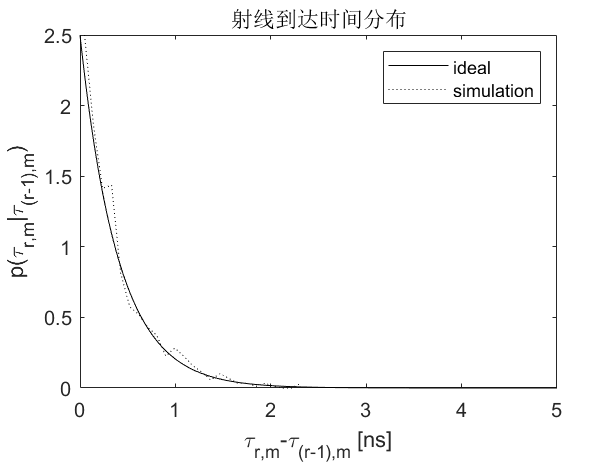


p_ray = lambda*exp(-lambda*t2);%理想指数PDF
h_ray = exprnd(1/lambda,1,1000);
[n_ray,x_ray] = hist(h_ray,25);

figure()
plot(t2,p_ray,'k')
hold on
plot(x_ray,n_ray*p_ray(1)/n_ray(1),'k:')
legend('ideal','simulation')
xlabel('\tau_{r,m}-\tau_{(r-1),m} [ns]')
ylabel('p(\tau_{r,m}|\tau_{(r-1),m})')
title('射线到达时间分布')

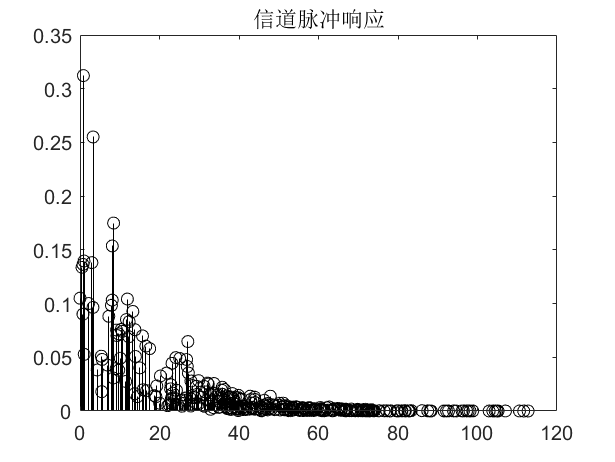


[h,t,t0,np] = SV_model_ct(Lam,lambda,Gam,gamma,N,power_nom,std_shdw);
figure()
stem(t(1:np(1),1),abs((h(1:np(1),1))),'ko')
title('信道脉冲响应')

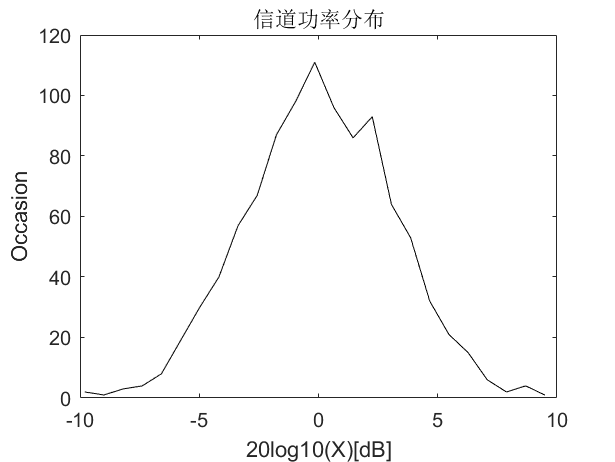

X = 10.^(std_shdw*randn(1,N)./20);
[temp,x] = hist(20*log10(X),25);
figure()
plot(x,temp,'k-')
title('信道功率分布')
xlabel('20log10(X)[dB]')
ylabel('Occasion')

function [h,t,t0,np]=SV_model_ct(Lam,lam,Gam,gam,num_ch,b002,sdi,nlos)
% 输入
%     Lam     :       簇到达率[Ghz](每纳秒的平均簇数量)
%     lam     :       射线到达率[GHz](每纳米平均射线数量)
%     Gam     :       簇衰减因子(ns)
%     gam     :       射线衰减因子(ns)
%     num_ch  :       随机信道数量
%     b002    :       第一簇第一射线功率
%     sdi     :       整个脉冲响应阴影衰落的标准差(dB)
%     nlos    :       NLOS信道标志
% 输出
%     h       :       num_ch列的矩阵，每一列表示信道模型的一个随机实现
%     t       :       信道路径所在时刻,和h相对应
%     t0      :       每一次实现第一簇到达时间
%     np      :       每一次实现的路径数
%     (t(1:np(k),k),h(1:np(k),k))表示第k个信道脉冲响应的实现

if nargin < 8 %los环境
    nlos=0;
end
if nargin < 7 %0dB
    sdi=0;
end
if nargin < 6 %第一簇第一射线功率=1
    b002=1;
end
h_len = 1000;
for k=1:num_ch
    tmp_h = zeros(h_len,1);
    tmp_t = zeros(h_len,1);
    if nlos
        Tc = exprnd(1/Lam);
    else
        Tc = 0;
    end
    t0(k) = Tc;
    path_ix = 0;
    while(Tc < 10*Gam) %簇循环
        Tr = 0;
        while(Tr<10*gam)%射线循环
            t_val = Tc+Tr;%射线到达时间
            bk12 = b002*exp(-Tc/Gam)*exp(-Tr/gam);%射线功率
            r=sqrt(randn^2+randn^2)*sqrt(bk12/2);
            h_val = exp(1j*2*pi*rand)*r;%均匀相位
            path_ix = path_ix+1;
            tmp_h(path_ix)=h_val;
            tmp_t(path_ix)=t_val;
            Tr = Tr + exprnd(1/Lam); %射线到达时间
        end
        Tc = Tc+exprnd(1/lam);  % 簇到达时间
    end
    np(k) = path_ix;% 该次实现的射线数
    [sort_tmp_t,sort_ix] = sort(tmp_t(1:np(k)));
    t(1:np(k),k)=sort_tmp_t;
    h(1:np(k),k) = tmp_h(sort_ix(1:np(k)));
    %施加对数阴影衰落
    fac = 10^(sdi*randn/20)/sqrt(h(1:np(k),k)'*h(1:np(k),k));
    h(1:np(k),k) = h(1:np(k),k)*fac;
end
end